# Skipping function calls

[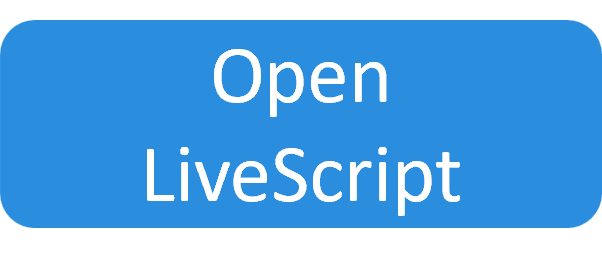](matlab:dxdzds.file='skipping_function_call';dxdzds.outFile=fullfile(pwd,dxdzds.file); copyfile(which(['user_' dxdzds.file]),[dxdzds.outFile '.mlx']);open(dxdzds.outFile);clear dxdzds;)

The normal operation of the `iterativeDisplay` is that within the loop, all the graphic functions should be called in the same order at every iteration. However, sometimes some data may not be available to the update a graphic object (and there are probably other situation in which you may want to skip a graphic function call). In that case, you should use the `skip` function.

The `skip` function simply replace a call to any functions.

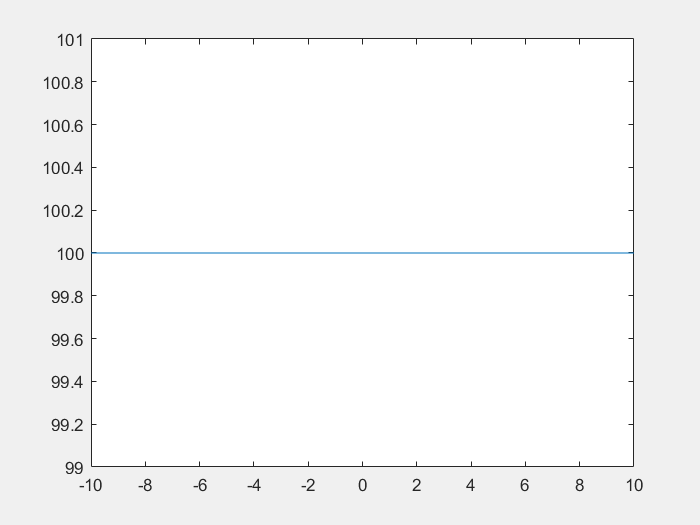

clearvars
close all
clc

id=iterativeDisplay;

hFig=id.figure;
set(hFig,'visible','on'); % Undock the figure from the live editor

x=linspace(-10,10,20);
for i=1:100
    if i<100
        id.newIteration;
    else
        id.finalIteration;
    end
    
    if i==1 || mod(i,10)==0
        % Update every 10 iterations
        id.plot(x,x*0+i);
    else
        id.skip('plot');
    end
    
   
    drawnow;
    pause(0.01)
end